# Proyecto Global Integrador - Control de PMSM

## Análisis de Linealización (Modelo LTI equivalente aumentado)

clear; clc;

### 1. Validación Simbólica del Polinomio Característico y Funciones de Transferencia

% Definición de variables simbólicas (reales y positivas)
syms s L_q_sym R_s_sym J_eq_sym b_eq_sym K_t_sym K_v_sym r_sym real positive

% Matriz del sistema M(s) obtenida agrupando los estados a la izquierda:
%  1) s*Theta_m - Omega_m = 0
%  2) (J_eq*s + b_eq)*Omega_m - K_t*I_qs = -1/r * T_l
%  3) K_v*Omega_m + (L_q*s + R_s)*I_qs = V_qs

M_s = [ s,                  -1,               0;
        0,     J_eq_sym*s + b_eq_sym,            -K_t_sym;
        0,               K_v_sym,  L_q_sym*s + R_s_sym ];

% Matriz de entrada B_in asociada al vector U(s) = [V_qs; T_l]'
B_in = [   0,    0;
           0, -1/r_sym;
           1,    0 ];

% Calculamos la matriz de transferencia del sistema G_matriz = inv(M_s) * B_in
disp('Matriz de Transferencia Completa del Sistema:')
G_matriz = simplify(M_s \ B_in)

% Aislamiento de las plantas individuales
G_v_raw = G_matriz(1,1); % Canal Tensión -> Posición
G_d_raw = G_matriz(1,2); % Canal Torque -> Posición

disp('Función de Transferencia Principal G_v(s) [V_qs -> Theta_m]:')
G_v = collect(G_v_raw, s)

disp('Función de Transferencia de Perturbación G_d(s) [T_l -> Theta_m]:')
G_d = collect(G_d_raw, s)

% Extracción del Polinomio Característico
[~, Dinominador_Comun] = numden(G_v_raw);
disp('Polinomio Característico del Motor Delta(s):')
Delta_s = collect(Dinominador_Comun, s)

% Separación del polo integrador (s=0)
Delta_em_s = simplify(Delta_s / s);
Delta_em_exp = collect(expand(Delta_em_s), s);

% Extraemos los coeficientes del polinomio de segundo orden (A*s^2 + B*s + C = 0
coeficientes = coeffs(Delta_em_exp, s);
C_sym = coeficientes(1); 
B_sym = coeficientes(2); 
A_sym = coeficientes(3);

% Cálculo simbólico de la frecuencia natural y amortiguamiento
wn_simbolico = sqrt(simplify(C_sym / A_sym));
zeta_simbolico = simplify((B_sym / A_sym) / (2 * wn_simbolico));

disp('--- Parámetros del Modo Electromecánico ---');
disp('Frecuencia natural no amortiguada (\omega_{n,em}):')
wn_em_sym = wn_simbolico
disp('Factor de amortiguamiento (\zeta_{em}):')
zeta_em_sym = zeta_simbolico

### 2. Analisis de Estabilidad a Lazo Abierto del Modelo LTI Aumentado

% Inicializacion del Workspace
run('init_sistema_completo.m')

% Constantes electromagneticas derivadas (asumiendo I_ds = 0)
K_t = (3/2) * Pp * lambda_m;
K_v = Pp * lambda_m;

#### 3.a) Analisis del Caso Nominal (Valores numéricos e Identificación)

% 1. Cálculo de Parámetros Dinámicos Nominales
wn_nom = sqrt((Rs_REF * beq_nom + K_t * K_v) / (Jeq_nom * L_q));
zeta_nom = (L_q * beq_nom + Rs_REF * Jeq_nom) / (2 * sqrt(Jeq_nom * L_q * (Rs_REF * beq_nom + K_t * K_v)));

% 2. Identificación de Autovalores (Polos)
% Modo Integrador (Cinematico)
p1_nom = 0;

% Modos Electromecanicos Conjugados
sigma_nom = zeta_nom * wn_nom;
wd_nom = wn_nom * sqrt(1 - zeta_nom^2);
p23_nom = [-sigma_nom + 1i*wd_nom; -sigma_nom - 1i*wd_nom];

% Modos Residuales Inobservables desde la mecanica
pd_nom = -Rs_REF / L_d;
pT_nom = -1 / (Rts_amb * Cts);

% 3. Identificacion de Ceros
zd_nom = -Rs_REF / L_q;

% --- IMPRESIÓN DE RESULTADOS (Formato Tabla Profesional) ---
disp('================================================================');

disp('   3.a) POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       ');

   3.a) POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       


disp('================================================================');

fprintf('\n--- 1. Subsistema Cinemático (Integrador) ---\n');


--- 1. Subsistema Cinemático (Integrador) ---


fprintf('Polo p1        = %0.2f\n', p1_nom);

Polo p1        = 0.00


fprintf('Efecto         : Posición libre sin resorte de retorno.\n');

Efecto         : Posición libre sin resorte de retorno.



fprintf('\n--- 2. Subsistema Electromecánico (Dominante) ---\n');


--- 2. Subsistema Electromecánico (Dominante) ---


fprintf('Polos p2,3     = %0.2f ± j%0.2f rad/s\n', real(p23_nom(1)), imag(p23_nom(1)));

Polos p2,3     = -88.49 ± j149.94 rad/s


fprintf('Frec. Natural  : wn_nom = %0.2f rad/s (%0.2f Hz)\n', wn_nom, wn_nom/(2*pi));

Frec. Natural  : wn_nom = 174.10 rad/s (27.71 Hz)


fprintf('Amortiguamiento: zeta   = %0.4f (Subamortiguado)\n', zeta_nom);

Amortiguamiento: zeta   = 0.5082 (Subamortiguado)


fprintf('Cte. de Tiempo : tau_em = %0.4f s (Decaimiento de la envolvente)\n', 1/sigma_nom);

Cte. de Tiempo : tau_em = 0.0113 s (Decaimiento de la envolvente)



fprintf('\n--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---\n');


--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---


fprintf('Polo eje d (pd) = %0.2f rad/s  --> tau_d = %0.4f s\n', pd_nom, -1/pd_nom);

Polo eje d (pd) = -154.55 rad/s  --> tau_d = 0.0065 s


fprintf('Polo Térm. (pT) = %0.4f rad/s  --> tau_T = %0.2f s\n', pT_nom, -1/pT_nom);

Polo Térm. (pT) = -0.0083 rad/s  --> tau_T = 120.00 s



fprintf('\n--- 4. Ceros de Transmisión ---\n');


--- 4. Ceros de Transmisión ---


fprintf('Cero Perturb.  : z_d = %0.2f rad/s\n', zd_nom);

Cero Perturb.  : z_d = -175.86 rad/s


fprintf('Efecto         : Adelanto de fase local ante torque de carga.\n');

Efecto         : Adelanto de fase local ante torque de carga.


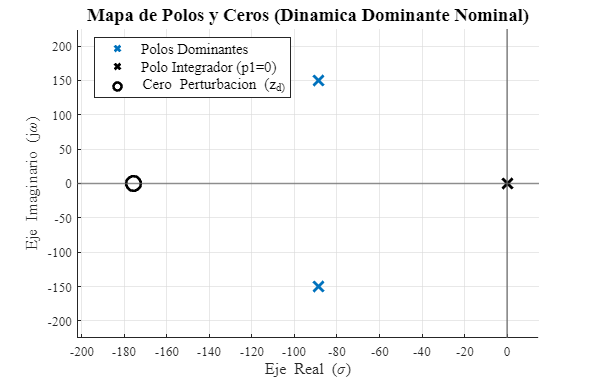

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_pz_nominal.pdf



% Instanciamos la clase gráfica profesional
plotter_nom = SignalPlotter("docs/img/");

polesList_nom = {p23_nom};
[fig_pz, ax_pz] = plotter_nom.plotPoleSweep(polesList_nom, 100, '', ...
    'Title', 'Mapa de Polos y Ceros (Dinamica Dominante Nominal)');

hold(ax_pz, 'on');

% Polo en el Origen
scatter(ax_pz, 0, 0, 120, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', 'Polo Integrador (p1=0)');

% Cero de Perturbacion
scatter(ax_pz, real(zd_nom), imag(zd_nom), 120, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', 'Cero Perturbacion (z_d)');

% Llamamos a la leyenda al final
legend(ax_pz, 'Location', 'best', 'FontName', plotter_nom.FontFamily, 'FontSize', plotter_nom.FontSizeLegend);

% --- AJUSTES DE ENCUADRE DINÁMICO ---
% Límite Y: Mantiene la proporción respecto a la frecuencia amortiguada
ylim(ax_pz, [-(wd_nom*1.5), (wd_nom*1.5)]); 

% Límite X: Busca el valor más negativo (el cero o los polos) y le da 15% de margen
limite_izq = min([real(p23_nom(1)), zd_nom]) * 1.15; 
limite_der = 15; % Margen fijo a la derecha para que el polo en el origen no quede pegado al borde

xlim(ax_pz, [limite_izq, limite_der]);   

hold(ax_pz, 'off');

% Exportación
plotter_nom.export(fig_pz, 'mapa_pz_nominal.pdf');

Parametros de Desempeño de la respuesta transitoria nominal

% 1. Cálculos de Desempeño
% Ganancia DC (K)
K_dc = K_t / (Jeq_nom * L_q * wn_nom^2);

% Tiempos característicos
tau_eq = 1 / sigma_nom;              % Constante de tiempo equivalente
tr = 1.8 / wn_nom;                   % Tiempo de subida (10% a 90% aprox)
ts = 4.6 / sigma_nom;                % Tiempo de establecimiento (Criterio 1%)
tp = pi / wd_nom;                    % Tiempo de pico

% Sobreimpulso y Error
Mp = 100 * exp((-pi * zeta_nom) / sqrt(1 - zeta_nom^2)); % Porcentaje de sobreimpulso
e_ss = abs(1 - K_dc);                % Error en estado estacionario (referencia unitaria)

% --- IMPRESIÓN DE RESULTADOS EN CONSOLA ---
disp('================================================================');

disp('   PARÁMETROS DE DESEMPEÑO TEMPORAL (Lazo Abierto - Velocidad)  ');

   PARÁMETROS DE DESEMPEÑO TEMPORAL (Lazo Abierto - Velocidad)  


disp('================================================================');

fprintf('Ganancia (K)         = %0.4f (rad/s)/V\n', K_dc);

Ganancia (K)         = 20.6993 (rad/s)/V


fprintf('Frec. Natural (wn)   = %0.2f rad/s\n', wn_nom);

Frec. Natural (wn)   = 174.10 rad/s


fprintf('Tasa Amortig. (sigma)= %0.2f rad/s\n', sigma_nom);

Tasa Amortig. (sigma)= 88.49 rad/s


fprintf('Factor Amortig.(zeta)= %0.4f -> ', zeta_nom);

Factor Amortig.(zeta)= 0.5082 -> 

if zeta_nom < 1
    fprintf('Sistema SUBAMORTIGUADO (Oscila)\n');
elseif zeta_nom == 1
    fprintf('Sistema CRÍTICAMENTE AMORTIGUADO\n');
else
    fprintf('Sistema SOBREAMORTIGUADO\n');
end

Sistema SUBAMORTIGUADO (Oscila)


fprintf('Frec. Amortig. (wd)  = %0.2f rad/s\n', wd_nom);

Frec. Amortig. (wd)  = 149.94 rad/s


fprintf('Cte. Tiempo (tau_eq) = %0.4f s\n', tau_eq);

Cte. Tiempo (tau_eq) = 0.0113 s


fprintf('Tiempo Subida (t_r)  = %0.4f s\n', tr);

Tiempo Subida (t_r)  = 0.0103 s


fprintf('Tiempo Establ. (t_s) = %0.4f s (Criterio 1%%)\n', ts);

Tiempo Establ. (t_s) = 0.0520 s (Criterio 1%)


fprintf('Tiempo Pico (t_p)    = %0.4f s\n', tp);

Tiempo Pico (t_p)    = 0.0210 s


fprintf('Sobreimpulso (M_p)   = %0.2f %%\n', Mp);

Sobreimpulso (M_p)   = 15.66 %


fprintf('Error Estacionario   = %0.2f\n', e_ss);

Error Estacionario   = 19.70


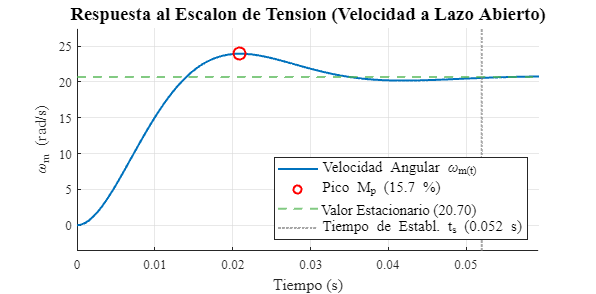



% =========================================================================
% --- PLOT: RESPUESTA AL ESCALÓN (VELOCIDAD) ---
% =========================================================================

% Creamos la función de transferencia de la VELOCIDAD omitiendo el integrador s=0
num_w = K_dc * wn_nom^2;
den_w = [1, 2*zeta_nom*wn_nom, wn_nom^2];
G_w = tf(num_w, den_w);

% Obtenemos los datos de la simulación ante un escalón unitario
[y_step, t_step] = step(G_w);

% Utilizamos tu clase SignalPlotter para mantener la estética profesional
plotter_step = SignalPlotter("docs/img/");
[fig_step, ax_step] = plotter_step.plotTime(t_step, y_step, ...
    'Title', 'Respuesta al Escalon de Tension (Velocidad a Lazo Abierto)', ...
    'XLabel', 'Tiempo (s)', ...
    'YLabel', '\omega_m (rad/s)', ...
    'Legends', {'Velocidad Angular \omega_m(t)'});

hold(ax_step, 'on');

% 1. Agregamos línea del valor en estado estacionario (Ganancia K)
yline(ax_step, K_dc, '--', 'Color', [0.3 0.7 0.3], 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Valor Estacionario (%.2f)', K_dc));

% 2. Marcamos el Sobreimpulso Máximo (Pico)
[max_y, idx_max] = max(y_step);
scatter(ax_step, t_step(idx_max), max_y, 80, 'o', 'MarkerEdgeColor', 'r', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Pico M_p (%.1f %%)', Mp));

% 3. Marcamos el Tiempo de Establecimiento (Línea vertical)
xline(ax_step, ts, ':', 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Tiempo de Establ. t_s (%.3f s)', ts));

% Actualizamos la leyenda para que lea las marcas nuevas
legend(ax_step, 'Location', 'southeast', ...
    'FontName', plotter_step.FontFamily, 'FontSize', plotter_step.FontSizeLegend);

hold(ax_step, 'off');

#### 3.b) Evaluación de Estabilidad Parcial y Completa

% Lógica de evaluación basada en la parte real de los polos
polos_totales = [p1_nom; p23_nom; pd_nom; pT_nom];
max_parte_real = max(real(polos_totales));

if max_parte_real < 0
    disp('CONCLUSIÓN: El sistema global es ASINTÓTICAMENTE ESTABLE.');
elseif max_parte_real == 0
    disp('CONCLUSIÓN: El sistema global es MARGINALMENTE ESTABLE (Debido al polo integrador p1=0).');
    disp('La derivada (velocidad omega_m) y los estados internos sí son asintóticamente estables (Estabilidad Parcial).');
else
    disp('CONCLUSIÓN: El sistema es INESTABLE.');
end

CONCLUSIÓN: El sistema global es MARGINALMENTE ESTABLE (Debido al polo integrador p1=0).


La derivada (velocidad omega_m) y los estados internos sí son asintóticamente estables (Estabilidad Parcial).


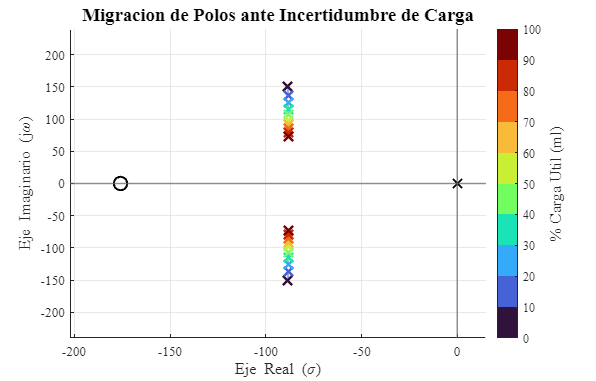

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_polos_migracion_LTI_Incertidumbre_Carga.pdf



%% 3.b) ANÁLISIS DE ROBUSTEZ Y MIGRACIÓN DE PROPIEDADES (INCERTIDUMBRE)
% Variamos de forma simultánea desde el caso "Mínima Carga" al caso "Máxima Carga"
num_steps = 10; % Cantidad de puntos a evaluar en el barrido

% Vectores de variación de parámetros (asumiendo variables _min y _max en Workspace)
% Si Jeq_min/max no están directas, reemplazar por su cálculo: bm + (bl_min/r^2), etc.
vec_beq = linspace(beq_min, beq_max, num_steps);
vec_Jeq = linspace(Jeq_min, Jeq_max, num_steps); 

% Inicialización de celdas para guardar la migración
polesList_em = cell(num_steps, 1);
etiquetas_leyenda = zeros(num_steps, 1);

for i = 1:num_steps
    % Extraemos parámetros de esta iteración
    beq_i = vec_beq(i);
    Jeq_i = vec_Jeq(i);
    
    % Recálculo de la dinámica dominante
    wn_i   = sqrt((Rs_REF * beq_i + K_t * K_v) / (Jeq_i * L_q));
    zeta_i = (L_q * beq_i + Rs_REF * Jeq_i) / ...
             (2 * sqrt(Jeq_i * L_q * (Rs_REF * beq_i + K_t * K_v)));
    
    % Cálculo de polos conjugados para esta iteración
    sigma_i = zeta_i * wn_i;
    wd_i    = wn_i * sqrt(1 - zeta_i^2);
    
    % Almacenamos el par de polos
    polesList_em{i} = [-sigma_i + 1i*wd_i; -sigma_i - 1i*wd_i];
    
    % Usaremos un indicador compuesto (ej. Masa de Carga Equivalente) para la leyenda
    % Aquí interpolo visualmente un porcentaje de carga para la etiqueta
    porcentaje_carga = (i-1)/(num_steps-1) * 100;
    etiquetas_leyenda(i) = porcentaje_carga;
end

%% MAPA DE POLOS Y CEROS EN EL PLANO S
% Instanciamos tu clase profesional
plotter = SignalPlotter("docs/img/"');

% Etiqueta simple para la barra de colores
etiqueta_colorbar = '% Carga Util (ml)'; 

[fig_rlocus, ax_rlocus] = plotter.plotPoleSweep(...
    polesList_em, ...
    etiquetas_leyenda, ...
    etiqueta_colorbar, ...
    'Title', 'Migracion de Polos ante Incertidumbre de Carga');

hold(ax_rlocus, 'on');

% Agregamos las marcas fijas del integrador y del cero
scatter(ax_rlocus, p1_nom, 0, 100, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
scatter(ax_rlocus, real(zd_nom), imag(zd_nom), 100, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Ajuste de límites idéntico para mantener consistencia visual entre ambos plots
xlim_min_sweep = min([real(p23_nom); zd_nom]) * 1.15;
xlim_max_sweep = 15;

xlim(ax_rlocus, [xlim_min_sweep, xlim_max_sweep]);
ylim(ax_rlocus, [-(wd_nom * 1.6), (wd_nom * 1.6)]);   

hold(ax_rlocus, 'off');

% Guardamos la figura para LaTeX
plotter.export(fig_rlocus, 'mapa_polos_migracion_LTI_Incertidumbre_Carga.pdf');